# Model Checker

This collection of classes could be used to generate models that fulfill special properties that prohibit some cases like: "Don't cross the crossroad when there is an other vehicle to collide with.".

## General concepts

The model checker allows to parallelize transition systems and synthesize them with büchi automatas to apply safety properties. This is used in an example to show how the state systems are used.

### Transition System

A transition system could be described as a tupel $\(TS = (S, Act, \rightarrow, I, AP, L)\)$, where

- $\(S\)$ is the set of all states,

- $\(Act\)$ is the set of all actions,

- $\(\rightarrow \subseteq S \times Act \times S \)$ is the transition relation,

- $\(I \subseteq S\)$ is the set of all initial states,

- $\(AP\)$ is the set of all atomic propositions and 

- $\(L: S \rightarrow 2^{AP}\)$ is a labeling function using the set of atomic propositions.

#### Functions

- parallelize - Parallelize two or more transition systems.

- plot - Plot transition system as digraph.

- synthesizeWithBA - Synthesize the transition system with a büchi automata.

#### Parallelization

Two or more transition systems that can take actions at the same time can be parallized to get a system showing all possible states and transitions from all subsystems. For that the transition systems get parallelized as follows:

- 
$$\(S_\parallel = S_1 \times S_2$$


- 
$$\(Act_\parallel = Act_1 \cup Act_2$$


- If $\(\alpha \in Act_1, \beta \in Act_2, s_1$ $\longrightarrow^{\alpha }$ $s'_1 \) with action \(\alpha\)$and $ \(s_2$ $\longrightarrow^{\beta }$ $ s'_2$, then $ \( \langle s_1,s_2 \rangle $$\longrightarrow^{\alpha }$ $\langle s'_1,s_2 \rangle,\langle s_1,s_2 \rangle $$\longrightarrow^{\beta }$ $\langle s_1,s'_2 \rangle\)$

- 
$$\(I_\parallel = I_1 \times I_2$$


- 
$$\(AP_\parallel = AP_1 \cup AP_2$$


- A label for a parallelized state is made by this rule: $\(L(\langle s_1,s_2 \rangle) = L_1(s_1) \cup L_2(s_2) \)$

#### Synthesize with BA

To get a transition system that fulfills a safety property described with a büchi automata both systems have to be synthesized.

The synthesized system $\(TS' = TS \otimes \mathcal{A} \)$ could be described with following equations:

- 
$$\(S' = S \times Q\)$$


- 
$$\( \forall s,t \in S, q,p \in Q \text{ with } s 
$$

$$\longrightarrow^{\alpha }$$
 
$$t \text{ and } q $$
 
$$\longrightarrow^{L\left(t\right)}$$

$$p \text{, then exists a transition } \langle s,q \rangle $$
 
$$\overset{\alpha }{\longrightarrow^{\prime } }$$

$$\langle t,p \rangle \)
$$


- 
$$I' = \{\langle s_0,q \rangle : s_0 \in I \text{ and }\exists q_0 \in Q_0 \text{ such that } q_0$$
 
$$\longrightarrow^{L\left(s_0 \right)}$$
 
$$q\}\$$


- 
$$\(AP' = Q\)$$


- 
$$L' : S \times Q \rightarrow 2^Q \text{ und } L'(\langle s,q \rangle) = \{q\} 
$$


Only states and transitions on a path that lead to an accepted state are allowed in the resulting transition system that fulfills the buchi automata.

Accepted states have following properties:

- 
$$L'(\langle s,q\rangle) \in F$$


- The state $  \( \langle s,q \rangle \) $could be reaced that means it exists a finite path fragment  $\(\pi_p'\)$ from any initial state $ \(\langle s_0,q_0 \rangle \in I'\)$ to $\(\langle s,q \rangle\)$ in$ \(TS'\)
$.

- The state $  \( \langle s,q \rangle \) $is in a direct cycle that means there exists a finite path fragment $\(\pi_c'\)$ from a state $ \(\langle s',q' \rangle \in Post(\langle s,q \rangle)\)$ to$\(\langle s,q \rangle\)$ in $ \(TS'\)
$.

### Büchi Automata

A büchi automata system could be described as a tupel $\(\mathcal{A} = (Q, \Sigma,\delta,Q_0,F)\)$, where

- $\(Q\)$ is the set of finite states,

- $\(\Sigma\)$ is the set of all symbols,

- $\(\delta \subseteq Q \times \Sigma \times Q\)$ is the transition relation,

- $\(Q_0 \subseteq Q \)$ is the set of all initial states,

- $\(F \subseteq Q \) $ is the set of all final states, also called accepted states.

### Example: Frogs and Leaps

A frog wants to jump along a Path $\(p\9$. At path segment $\(p_4\)
$ he runs into a problem. There is a river and only every second time is a leafe coming that he can use to cross the river. If there is no leafe he has to wait, because he is afraid of water.

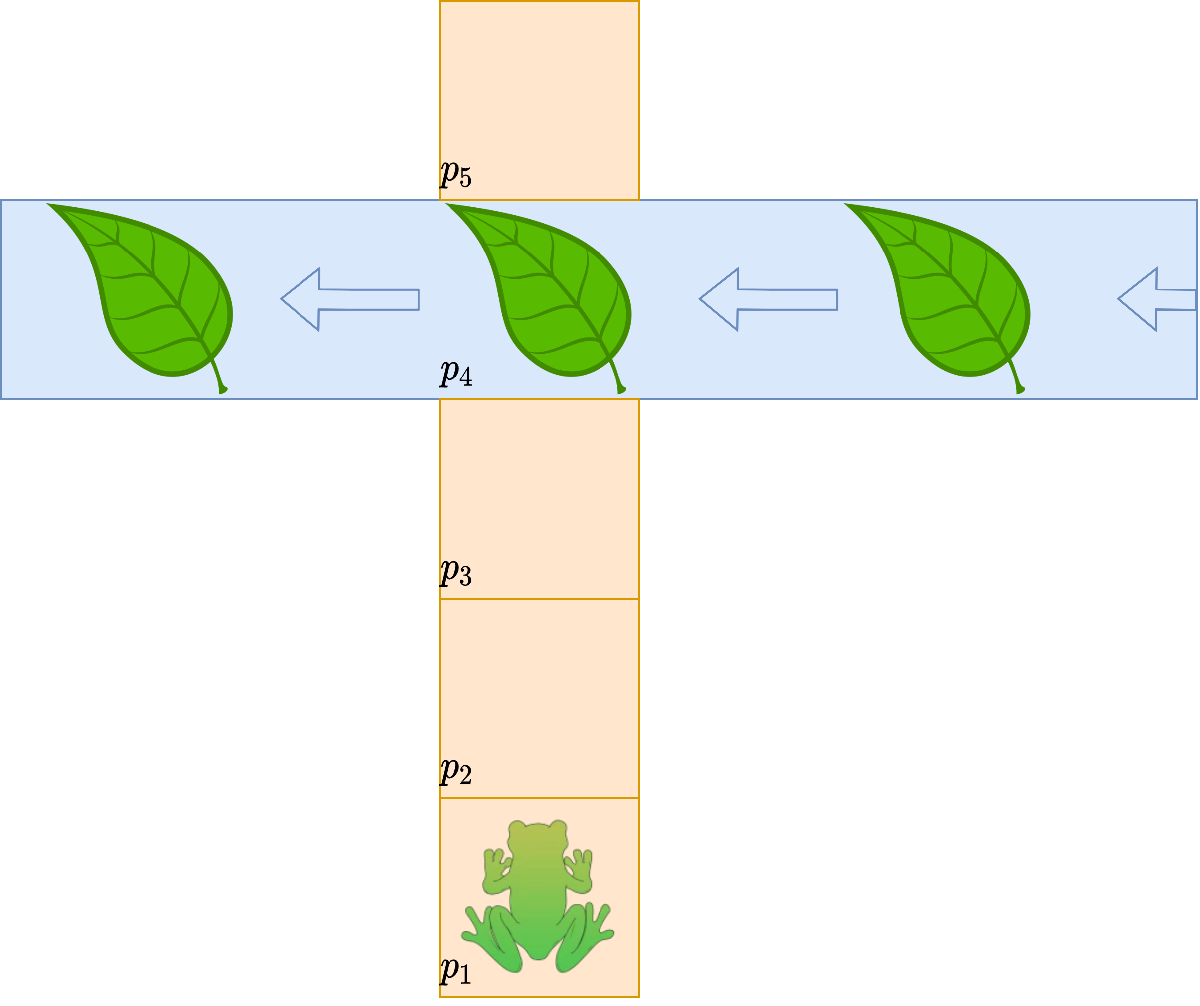

In the picture below is the transition system of the frog. Every state is a path fragment and he transitions between them with a jump. At state $\(p_3\)$ he can wait in front of the river and at state $\(p_5\)$ he has to wait because the path is at his end.

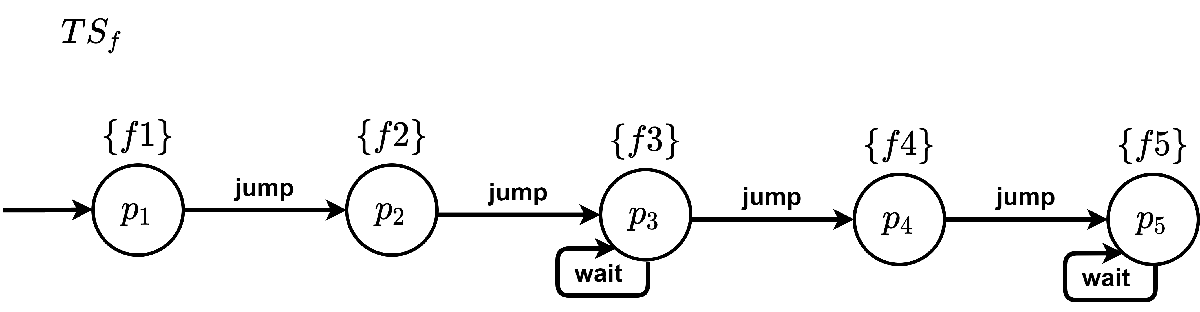

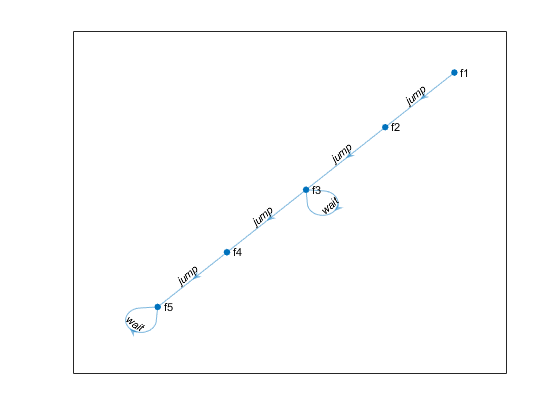

% States
S = ["p1" "p2" "p3" "p4" "p5"];

% Actions
Act = ["jump" "wait"];

% Transitions
% source | target | action
Tr =   [S(1) S(2) Act(1);
        S(2) S(3) Act(1);
        S(3) S(3) Act(2);
        S(3) S(4) Act(1);
        S(4) S(5) Act(1);
        S(5) S(5) Act(2);];

% Initial states
I = S(1);

% Atomic propositions
AP = ["f1" "f2" "f3" "f4" "f5"];

% Labels
L = [S' AP'];

% generate transition system
TSf = TransitionSystem(S, Act, Tr, I, AP, L);
TSf.plot();

The transition system of a leaf at path fragment $\(p_4\)$ is simpler. There is only the possibility that there is a leave or not and this state is constantly changing.

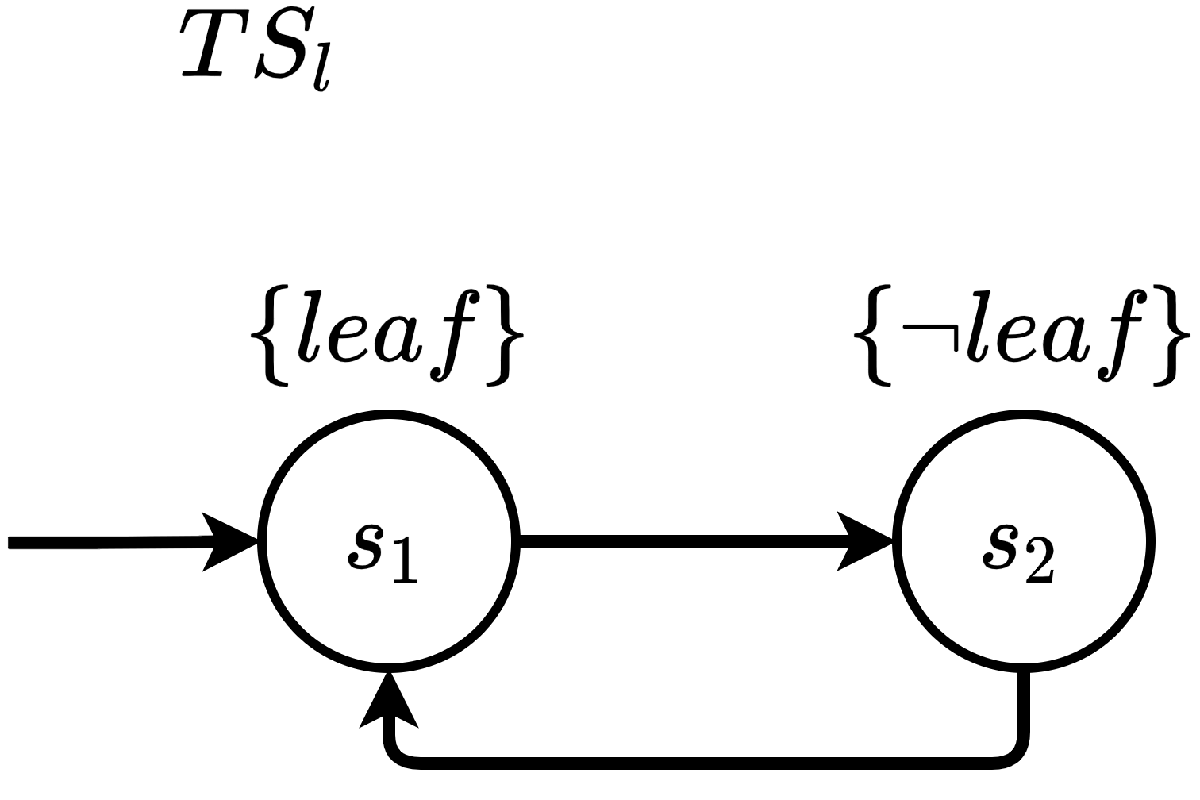

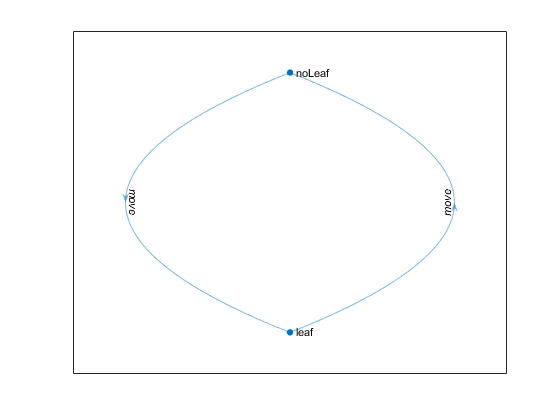

% States
S = ["s1" "s2"];

% Actions
Act = "move";

% Transitions
% source | target | action
Tr =   [S(1) S(2) Act(1);
        S(2) S(1) Act(1);];

% Initial states
I = S(1);

% Atomic propositions
AP = ["leaf" "noLeaf"];

% Labels
L = [S' AP'];

% generate transition system
TSl = TransitionSystem(S, Act, Tr, I, AP, L);
TSl.plot();

To get a system showing all possible states that could happen at the same time, the two transition systems have to be parallized.

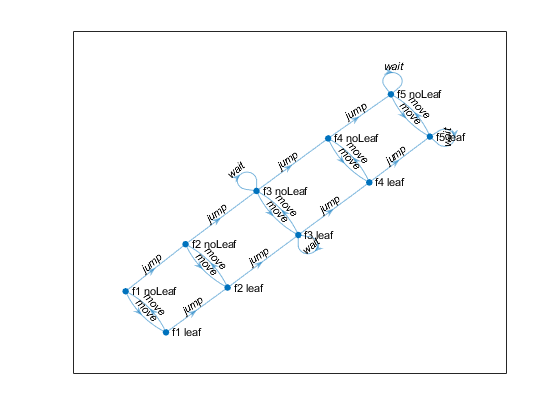

TSp = TransitionSystem.parallelize([TSf TSl]);
TSp.plot();

To make the example easier it is assumed that every time the frog takes an action the leave also moves. The result with all valid states and transitions is shown in the next picture.

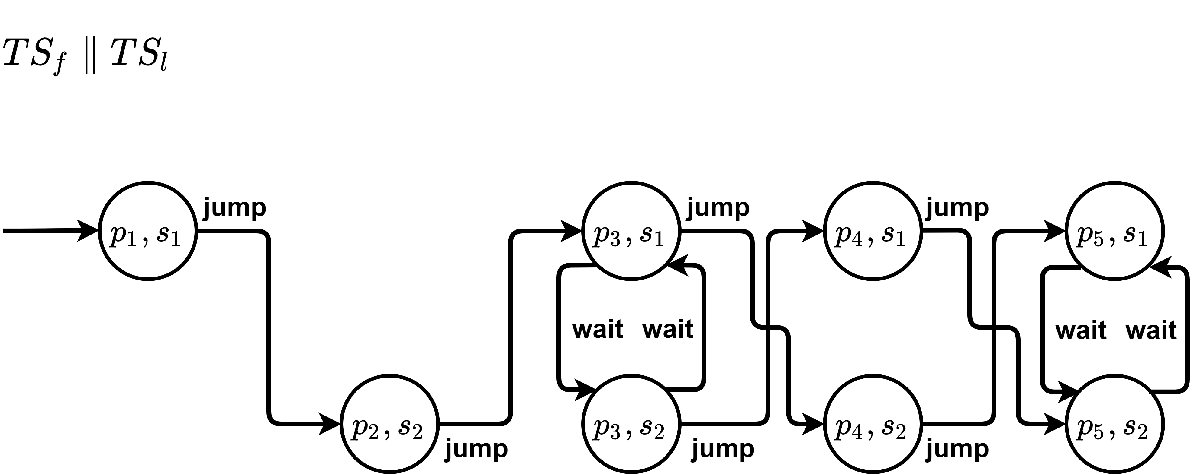

To prevent the frog from falling into water, the parallelized transition system $\(TS_p\)$ should not reach the state $\langle p_4,s_2 \rangle$ when the frog reaches the river but there is no leaf. This can be formulated in a safety property as LTL equation:


$$\varphi = \lnot(f_{4} \land \lnot leaf) \mathcal{U} f_{5}$$


State $f_4$ and $\lnot leaf$should not be true at the same time until the frog reaches state $f_5$.

Through online translators like [SPOT](https://spot.lrde.epita.fr/app/) this formular can be converted to a büchi automaton as shown in the next picture.

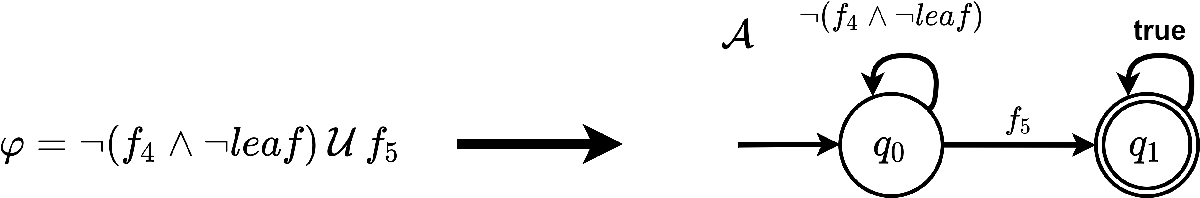

% States Q
states = ["q0" "q1"];

% Symbols Sigma (transition conditions)
% conditions for the transition between states

symbols = { @(allAPs) (~(allAPs.("f4") && allAPs.("noLeaf"))) ...
            @(allAPs) (allAPs.("f5")) ...
            @(allAPs) (1)};

% Transitions delta
transitions = {"q0" "q0" symbols{1}; ...
    "q0" "q1" symbols{2}; ...
    "q1" "q1" symbols{3}};

% Initial states
initialStates = "q0";

% Final states
finalStates = "q1";

% Construct Buchi Automata
BAsp = BuchiAutomata(states, symbols, transitions, initialStates, finalStates);

To apply the safety property in form of a büchi automata to the transition system. It has to synthesized with it. The result is a transition system that fulfills every time the safety property. 

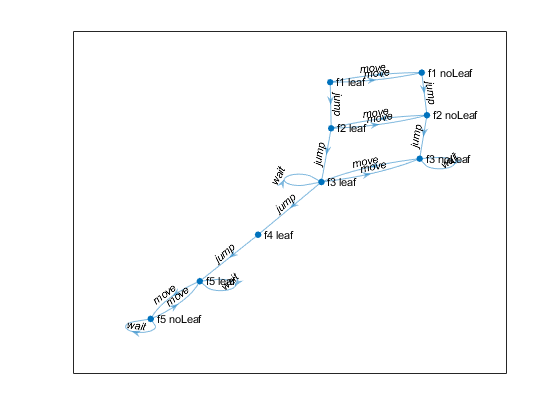

TSp.synthesizeWithBA(BAsp, true);
TSp.plot();

The result can be seen in the next picture. The green path shows an option to get to the end of the path.

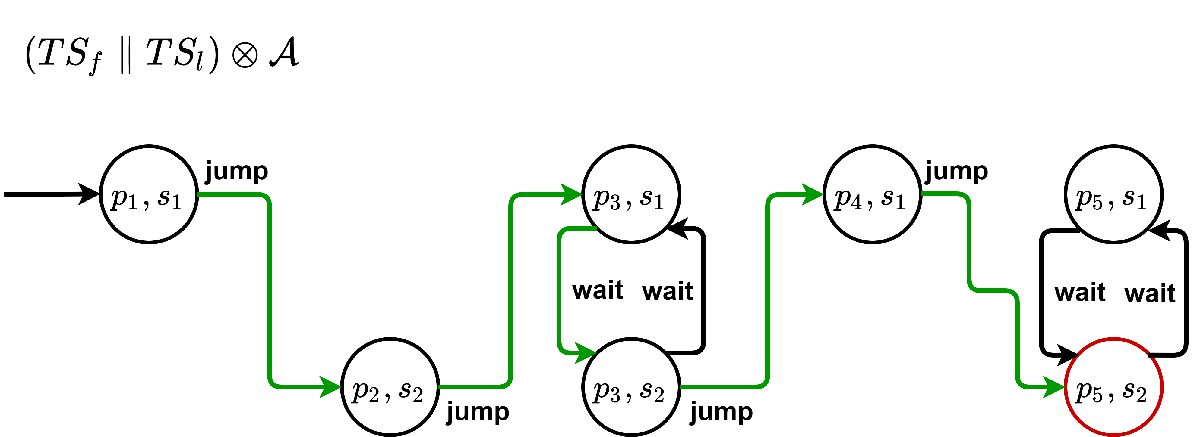

## Crossroad verification

The files in the folder "Crossroad" could be used to verify decisions from a crossroad manager in the framework [MOBATSim](https://github.com/MOBATSim/MOBATSim). For every decision a model from the crossroad with safety properties is build and used for verification.

### TSvehicle

The crossroad model consists of the models from different vehicles on the crossroad. In the class [TSvehicle](matlab:open('./Crossroad\TSvehicle.m')) the transition system shown in the following picture is generated.

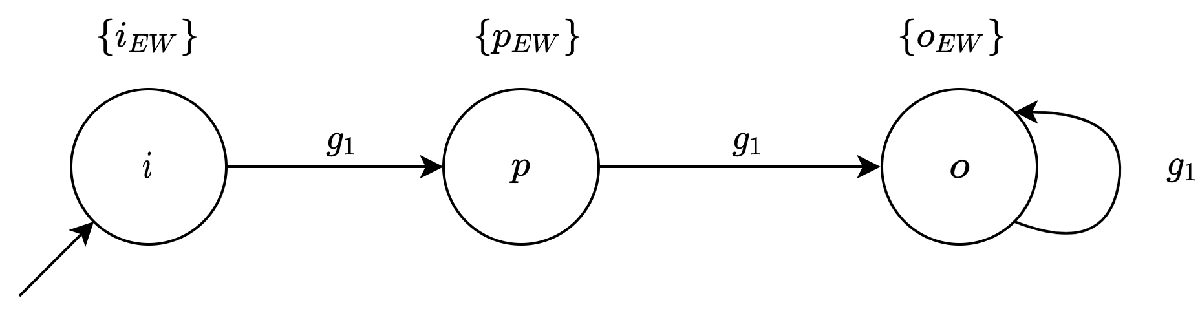

A vehicle is starting in input state "i" on the crossroad. With the Go-Action "g1" the vehicle can get on the crossroad to the state passing "p". With the next action the vehicle is leaving the crossroad. The labels are showing in which direction the vehicle is passing the crossroad. In this example from east to west.

direction = "ew"

direction = "ew"

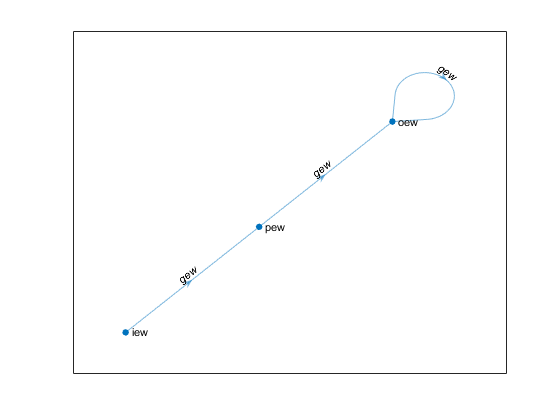


% States
S = ["i" "p" "o"];

% Actions
Act = "g"+direction;

% Transitions
% source | target | action
Tr = [S(1) S(2) Act(1);
    S(2) S(3) Act(1);
    S(3) S(3) Act(1)];

% Initial states
I = S(1);

% Atomic propositions
AP = [S(1)+direction S(2)+direction S(3)+direction];

% Labels
L = [S' AP'];

% generate transition system object
TS = TransitionSystem(S, Act, Tr, I, AP, L);
TS.plot();

### TScrossroad

The transition system of a crossroad ([TScrossroad](matlab:open('./Crossroad\TScrossroad.m'))) is the parallelization of every vehicle on the crossroad at the specific moment. The following picture is showing an example where two vehicles are on the crossroad. One in east-west direction, the other one from west to north.

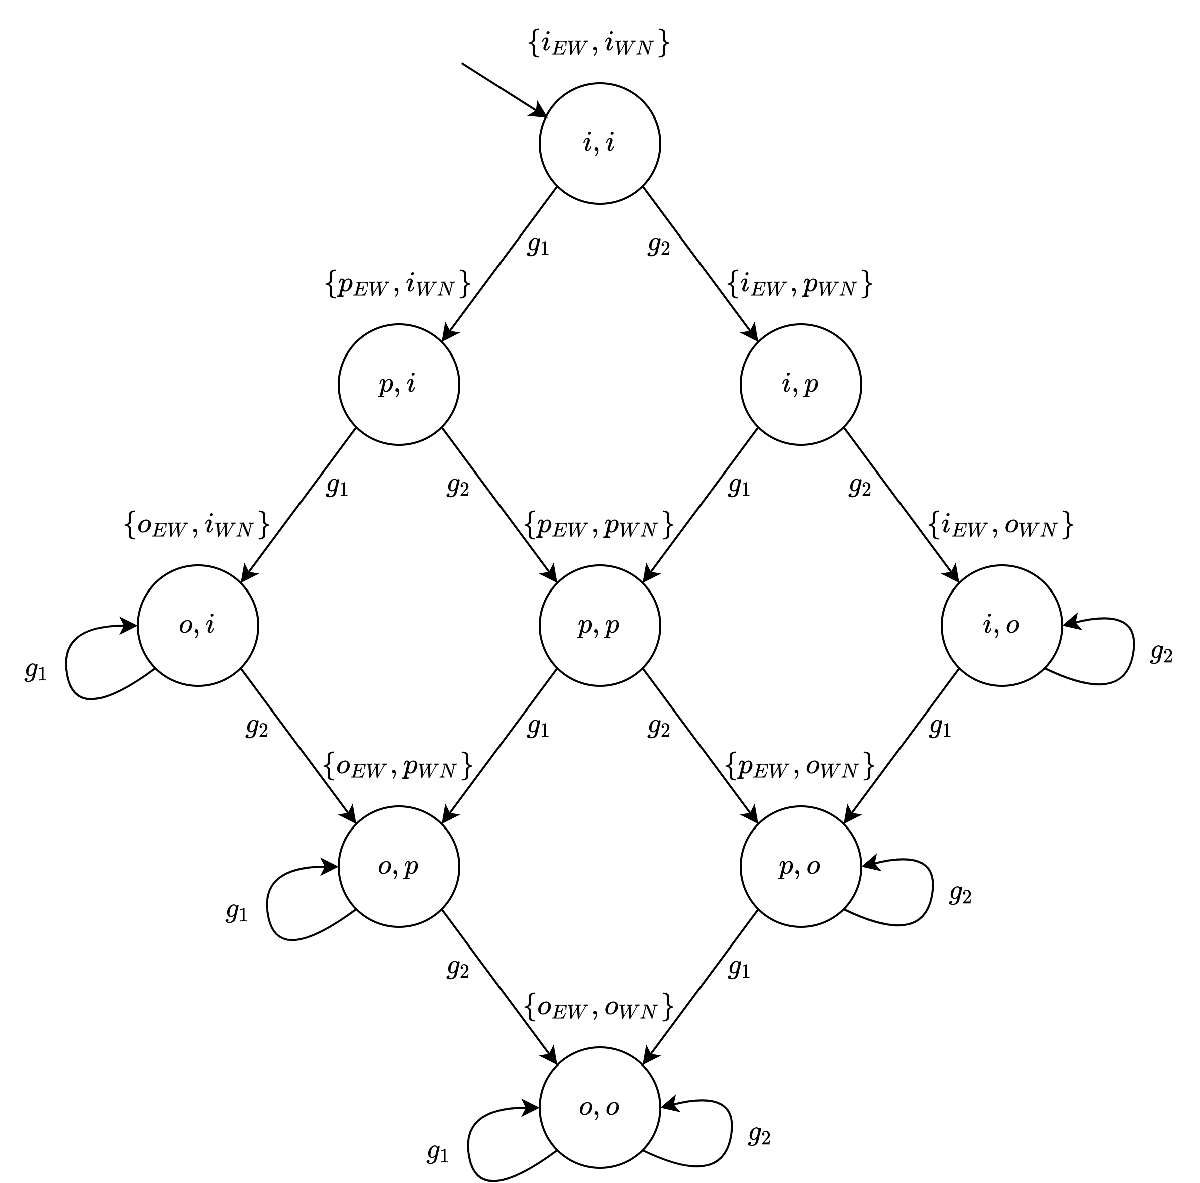

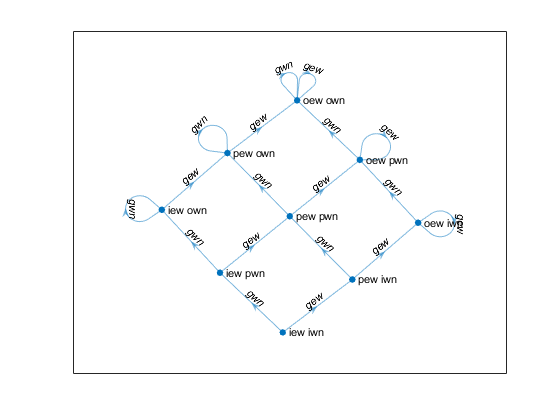

TSew = TSvehicle("ew");
TSwn = TSvehicle("wn");

% Parallelize all this vehicle transition systems to one crossroad
% transition system
TSp = TransitionSystem.parallelize([TSew TSwn]);
% Construct transition system
TS = TransitionSystem(TSp.states, TSp.actions, TSp.transitions, TSp.initialStates, TSp.atomicProps, TSp.labels);
TS.plot();

### Safety Properties

To generate safety properties that prevent the collision from crossing paths on a crossroad safety properties are used. For example the two vehicles in EW- and WN- direction could not pass a crossroad at the same moment without a collision. To prevent this the function [getSPcrossingPaths.m](matlab:open('./Crossroad\getSPcrossingPaths.m')) could be used. By adding a property that does not allow the passing of this two directions, the collision is excluded. This safety property is then synthesized with the transition system of the crossroad.

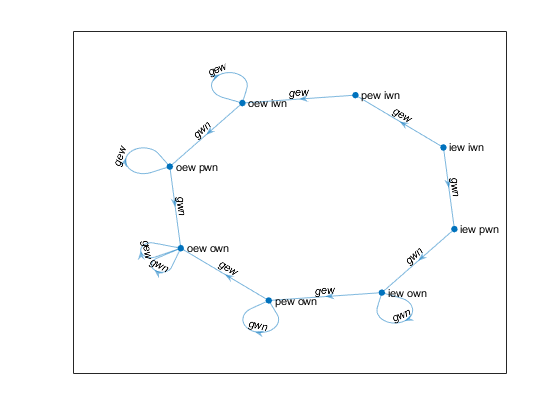

% TS vehicles
TSew = TSvehicle("ew");
TSwn = TSvehicle("wn");
crossingPaths = ["ew", "wn"];

% TS crossroad
TS = TScrossroad([TSew TSwn]);
safetyProperty = getSPcrossingPaths(crossingPaths);

% Synthesize a model that does not contain any states with vehicles
% colliding on crossing paths
TS.synthesizeWithSPs(safetyProperty, crossingPaths);
TS.plot();

The result with the excluded state in the middle can be seen in the following picture.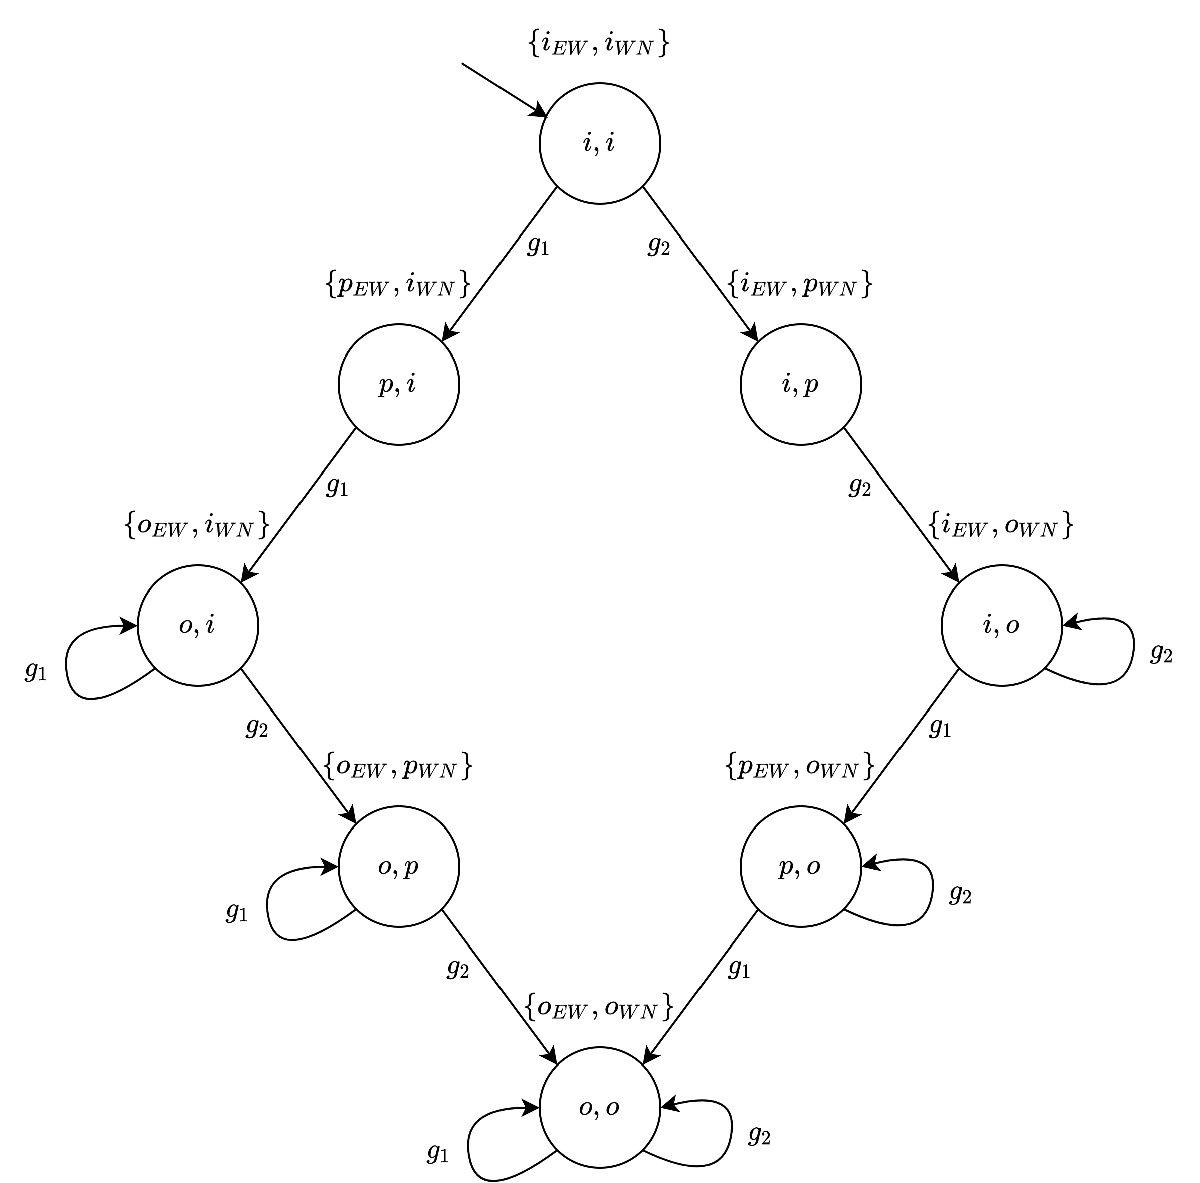

## Verify a MOBATSim crossroad

The method "verifyModel" from class [TScrossroad](matlab:open('./Crossroad\TScrossroad.m')) could be used to verify a decision from a crossroad manager. As input the method needs all directions from vehicles that should be allowed to pass the crossroad at the next moment, the directions from the vehicles already on the crossroad and all crossing paths at the crossroad. With this input a crossroad model could be build up and the commands from the crossroad managers could be checked with this model.

## Vehicles on Crossroad example

A complete example with all safety properties for a crossroad with four incoming lanes from four directions could be found in [VehcilesOnCrossroad.m](matlab:open('./Examples\VehiclesOnCrossroad.m')). Different number of vehicles could be used for models with different complexities.